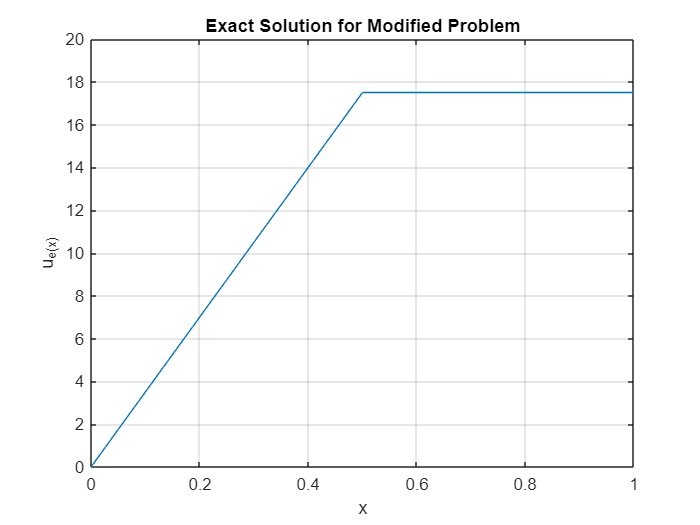

clc; 
clear;
syms x f(x) u_e(x)

a = 1;

f(x) = 0;

% Midpoint and Point Load
x_P_loc = 0.5;
P = -20;  % Magnitude of the point load

%----------------------------------------------------------------------------
deqn = a*diff(u_e,x,2) == f + P*dirac(x - x_P_loc);

Value1 = 0;
Value2 = 15;

ic = u_e(0) == Value1;
d_ue(x)= diff(u_e,x);
ic2 = d_ue(1) == Value2;

u_exact = dsolve(deqn,[ic ic2]);
exact_sol_f = u_exact;

% Plot the solution
x_values = linspace(0, 1, 1000);
u_values = zeros(size(x_values));

for i = 1:length(x_values)
    x_val = x_values(i);
    if x_val < x_P_loc
        u_values(i) = double(subs(exact_sol_f, x, x_val));
    else
        u_values(i) = double(subs(exact_sol_f, x, x_P_loc));
    end
end

plot(x_values, u_values);
xlabel('x');
ylabel('u_e(x)');
title('Exact Solution for Modified Problem');
grid on;
ylim([0 20])